
close all;
clear all;

file_date = '2024-01-11';
file_list = [1012:11:1056 1065:11:1087 1096 1109:11:1131 1139 1148];



for k = 1:length(file_list)

    maindir=['\\Artemis-pc\e\Data\',file_date,'\Abs-',num2str(file_list(k)),'\'];
    load([maindir,'\Temp.mat']);

    holding(k) = hold_time;
    T_H(k) = tempH;
    T_H_err(k) = tempH_error;
    T_V(k) = tempV;
    T_V_err(k) = tempV_error;

end


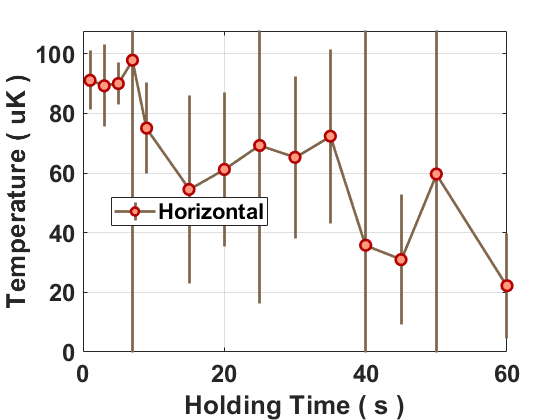


f1 = figure; 

I1 = errorbar(holding,T_H,T_H_err,'o-',...
    'CapSize',0,'LineWidth',2,'MarkerSize',8,'Color',[0.5,0.4,0.3],...
    'MarkerEdgeColor',[0.7 0 0],'MarkerFaceColor',[1 0.6 0.5]);

xlim([0 max(holding)]);
ylim([0,max(T_H)*1.1]);
set(gca,'Fontsize',18,'FontName','Arial','FontWeight','bold');
grid on;

xlabel('Holding Time ( s )');
ylabel('Temperature ( uK )');
legend('Horizontal','Location','best');

set(gcf,'Visible','on');

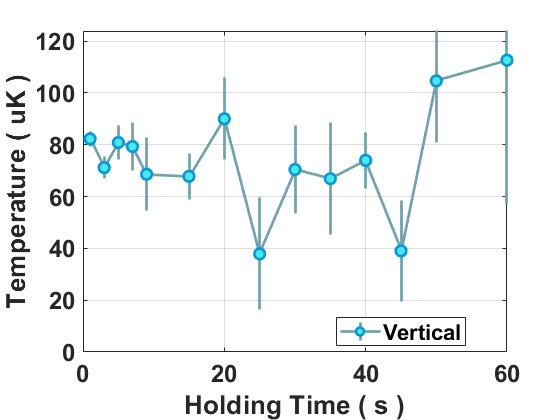


f2 = figure;

I2 = errorbar(holding,T_V,T_V_err,'o-',...
    'CapSize',0,'LineWidth',2,'MarkerSize',8,'Color',[0.45,0.63,0.67],...
    'MarkerEdgeColor',[0.04,0.59,0.83],'MarkerFaceColor',[0.29,0.91,0.91]);


xlim([0 max(holding)]);
ylim([0,max(T_V)*1.1]);
set(gca,'Fontsize',18,'FontName','Arial','FontWeight','bold');
grid on;

xlabel('Holding Time ( s )');
ylabel('Temperature ( uK )');
legend('Vertical','Location','best');

set(gcf,'Visible','on');


savefig(f1,[maindir,'\T_H_vs_Hold.fig']);
saveas(f1,[maindir,'\T_H_vs_Hold.png']);

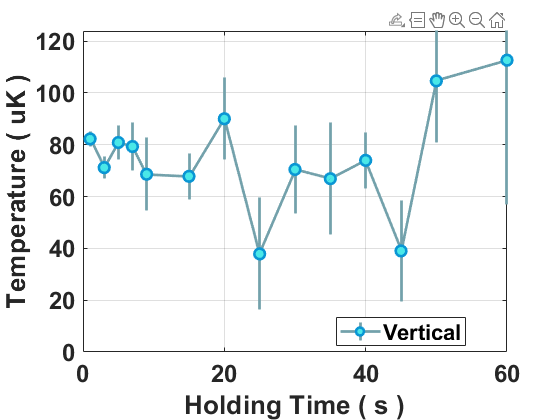


savefig(f2,[maindir,'\T_V_vs_Hold.fig']);
saveas(f2,[maindir,'\T_V_vs_Hold.png']);


save([maindir,'\T_vs_Hold.mat']);